# Data

Pressure_Data = xlsread('AE545_LAB_1_Data.xlsx'); %#ok<XLSRD>
Airfoil_Data = xlsread('naca_coordinates.xlsx'); %#ok<XLSRD>
Pressures = Pressure_Data(4:end,1:7);
Static = Pressure_Data(2,1:7);
Total = Pressure_Data(3,1:7);

# Variables

c = .195; %m
rho_air = 1.225; %kg/m^3
mu_air = 1.78E-7; %kg/m*s
rho_mono = .826*1000; %kg/m^3
g = 9.81; %m/s^2

# Reynolds Number

V_free = zeros(1,7);
Re = zeros(1,7);
for i = 1:7
    V_free(i) = sqrt((2*rho_mono*g*abs(Pressure_Data(3,i)-Pressure_Data(2,i)))/rho_air);
    Re(i) = (rho_air.*V_free(i).*c)/mu_air;
end

# Coefficients

Cp = zeros(48,7);
Cn = zeros(1,7);
Ca = zeros(1,7);
Cl = zeros(1,7);
Cd = zeros(1,7);
CmLE = zeros(1,7);
Cmc_4 = zeros(1,7);

AoA_deg = [-8, -4, 0, 4, 8, 12, 16];
alpha_rad = deg2rad(AoA_deg);

lower_x = flip(Airfoil_Data(25:48,2));
lower_y = flip(Airfoil_Data(25:48,3));

xc_upper = Airfoil_Data(1:24,2);
xc_lower = Airfoil_Data(25:48,2);
yc_upper = Airfoil_Data(1:24,3);
yc_lower = Airfoil_Data(25:48,3);
delta_xc_upper = gradient(Airfoil_Data(1:24,2));
delta_xc_lower = gradient(lower_x);
delta_yc_upper = gradient(Airfoil_Data(1:24,3));
delta_yc_lower = gradient(lower_y);


for i = 1:7
    for j = 1:48
        Cp(j,i) = (Pressures(j,i)-Static(i))/(Total(i)-Static(i));
    end
end

for i = 1:7
    Cn_lower = sum(Cp(25:48,i) .* delta_xc_lower);
    Cn_upper = sum(Cp(1:24,i) .* delta_xc_upper);
    Cn(i) = Cn_lower - Cn_upper;

    Ca_lower = sum(Cp(25:48,i) .* delta_yc_lower);
    Ca_upper = sum(Cp(1:24,i) .* delta_yc_upper);
    Ca(i) = Ca_upper - Ca_lower;

    cm1(i) = sum(Cp(1:24,i) .* delta_xc_upper .* xc_upper);
    cm2(i) = sum(Cp(25:48,i) .* delta_xc_lower .* xc_lower);
    cm3(i) = sum(Cp(1:24,i) .* delta_yc_upper .* yc_upper);
    cm4(i) = sum(Cp(25:48,i) .* delta_yc_lower .* yc_lower);
    CmLE(i) = cm1(i)-cm2(i)+cm3(i)-cm4(i);

    Cl = (Cn.*cos(alpha_rad))-(Ca.*sin(alpha_rad));
    Cd = (Cn.*sin(alpha_rad))+(Ca.*cos(alpha_rad));

    Cmc_4(i) = CmLE(i) + .25.*Cl(i);
end

# Figures

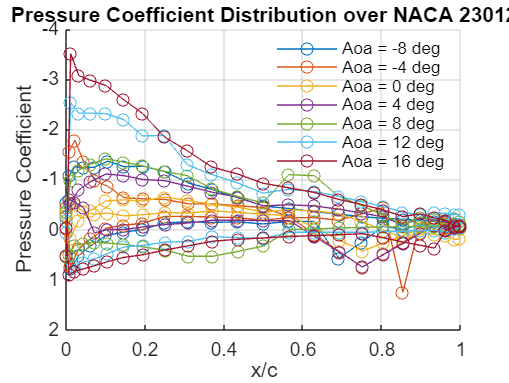

%Cp vs x/c
figure;
hold on;
colors = lines(num_aoa);
for k_aoa = 1:num_aoa
    cp_column= Cp_matrix(:, k_aoa);
    legend_label = sprintf('Aoa = %.0f deg', AoA_deg(k_aoa));
    plot(x_c, cp_column, 'o-', 'Color', colors(k_aoa,:), 'DisplayName', legend_label);
end
set (gca, 'YDir', 'reverse');
grid on;
title('Pressure Coefficient Distribution over NACA 23012');
xlabel('x/c');
ylabel('Pressure Coefficient');
legend('show', 'Location', 'best');
hold off;

legend('show','NumColumns',2,'Location','southoutside');
legend boxoff;

grid on;

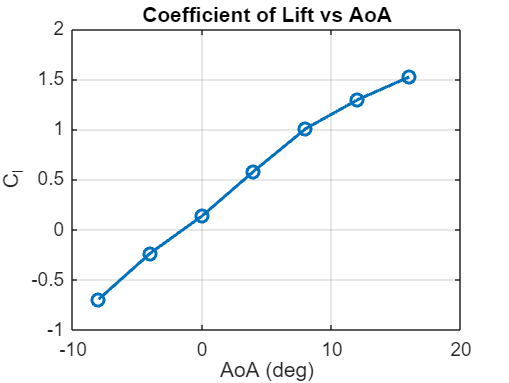


% 2) Cl vs AoA
figure;
plot(Pressure_Data(1,1:7), Cl, 'o-','LineWidth',1.5);
xlabel('AoA (deg)');
ylabel('C_l');
title('Coefficient of Lift vs AoA');
grid on;

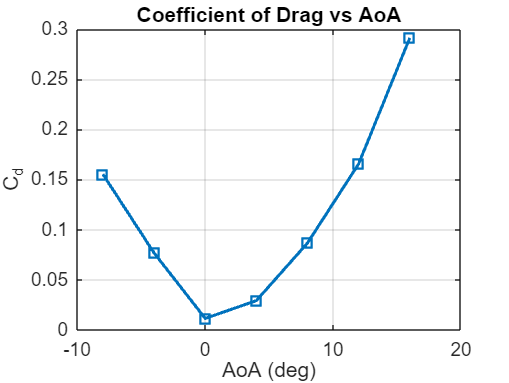


% 3) Cd vs AoA
figure;
plot(Pressure_Data(1,1:7), Cd, 's-','LineWidth',1.5);
xlabel('AoA (deg)');
ylabel('C_d');
title('Coefficient of Drag vs AoA');
grid on;

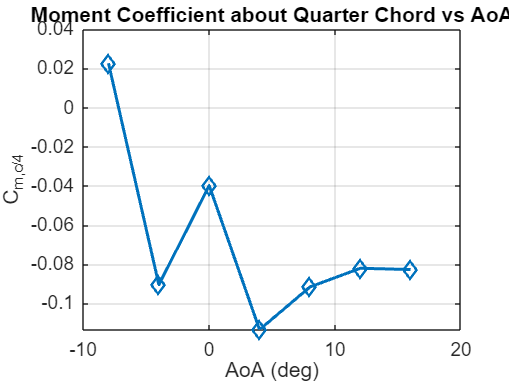


% 4) Cm,c/4 vs AoA
figure;
plot(Pressure_Data(1,1:7), Cmc_4, 'd-','LineWidth',1.5);
xlabel('AoA (deg)');
ylabel('C_{m,c/4}');
title('Moment Coefficient about Quarter Chord vs AoA');
grid on;

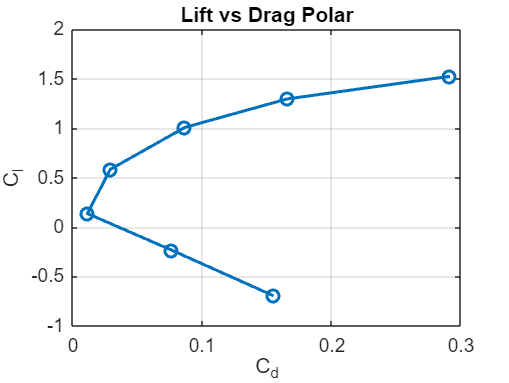


plot(Cd, Cl, 'o-', 'LineWidth', 1.5, 'MarkerSize', 6);
xlabel('C_d');
ylabel('C_l');
title('Lift vs Drag Polar');
grid on;


% 5) Results Table
ResultsTable = table(Pressure_Data(1,1:7)', V_free', Re', Cl', Cd', Cmc_4', ...
    'VariableNames', {'AoA_deg','V_free','Re','Cl','Cd','Cm_c4'});
disp(ResultsTable);

    AoA_deg    V_free        Re           Cl          Cd         Cm_c4  
    _______    ______    __________    ________    ________    _________

      -8       36.007    4.8321e+07    -0.69577     0.15524     0.022659
      -4       32.532    4.3658e+07    -0.23513    0.076643    -0.090518
       0       34.697    4.6563e+07     0.13679    0.011241    -0.039846
       4       34.697    4.6563e+07     0.58394    0.029024     -0.11347
       8       34.887    4.6818e+07      1.0074    0.086575    -0.091653
      12       34.887    4.6818e+07      1.2955     0.16562    -0.082109
      16       37.799    5.0726e+07      1.5245     0.29141    -0.082728

